clearvars;
addpath("../helperFunctions/");

# Least Square Method - Image Source Method

### Initial Parameters

n = 3; spacing = 0.01;
room = [6,6,5];
order = 5;
beta = [0.8,0.75,0.85,0.77,0.1,0.1]; alpha = 1-beta.^2;
f = 200; c = 343; omega = 2*pi*f ; phase = 0;
rho_k = omega/c;
S = my_sph2cart(deg2rad(120),deg2rad(305),2);
mag = 10;
[rho_s,the_s,phi_s] = my_cart2sph(S);
rx = -n:spacing:n;
ry = rx;
sz = [length(ry) length(rx)];
rz = zeros(size(rx));
r = [rx;ry;rz];
R = 0.5; % region of interrest
N = ceil(exp(1)*rho_k*R/2);


### Monopole Wave - Energy

According to http://www.apsipa.org/proceedings_2015/pdf/223.pdf

We can express the average sound energy within the control region $S$ as


$$\int_S|P(\mathbf x)|^2dS = \int_0^R\int_0^\pi\int_0^{2\pi}P(\mathbf x)\overline{P(\mathbf x)}r^2dr\sin\theta d\theta d\phi = \sum_{n,m}a_{nm}\overline{a_{nm}}\int_0^Rj_n^2(kr)r^2dr$$



$$SPL=10log\bigg(\frac{P}{P_{ref}}\bigg)$$


where


$$P_{ref} = 20\mu P$$


$P = 

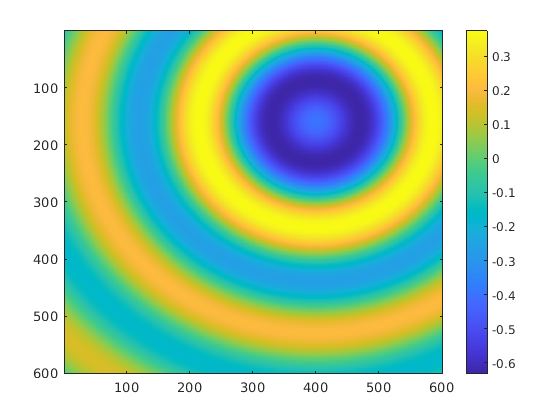

wave1 = monopoleWave(S,r,mag,rho_k,0);
figure;
imagesc(imag(wave1)); colorbar;

### Monopole Wave - Image Source Method

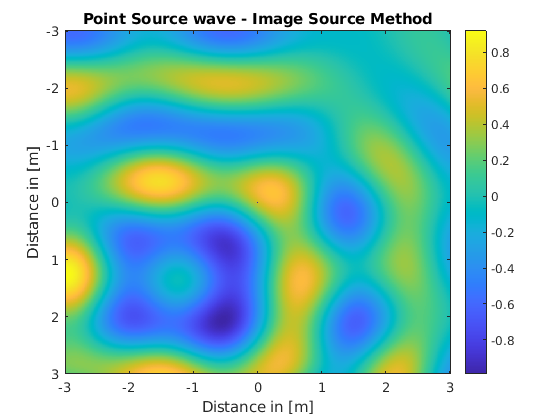

figure;
wave = ISM2d(rx,ry,rz,S,room,mag,phase,omega,c,alpha,order,spacing,1);

figure;

### Microphone Array 

waveFun = @(R,the,phi) ISMspherical(rho_s,the_s,phi_s,R,the,phi,room,mag,phase,omega,c,alpha,order);
[Blm,mic] = harmonicCoefficients(R,rho_k,N,waveFun,n,wave,0);
B = Blm(1,1);
for idl=2:(N+1)
    l=idl-1;
    for idm=1:(2*l+1)
        B = [B Blm(idl,idm)];
    end
end
B = B.';

### Loudspeaker

[nlspkr,lspkr] = loudspeaker_positions(room,1);

### 3D Plot

setupPlot(wave,mic,lspkr,S,R,n,spacing,3,0);

### 2D Plot with wave

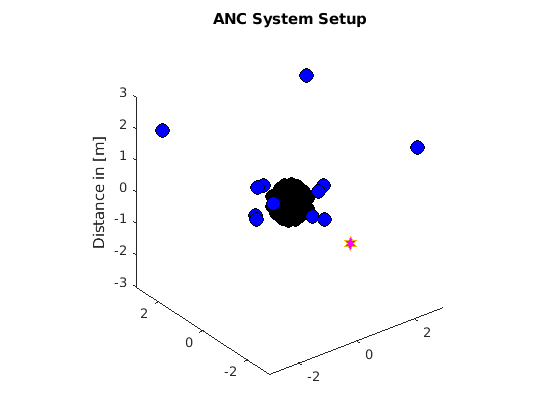

setupPlot(wave,mic,lspkr,S,R,n,spacing,2,1);

### Loudspeaker Coefficients

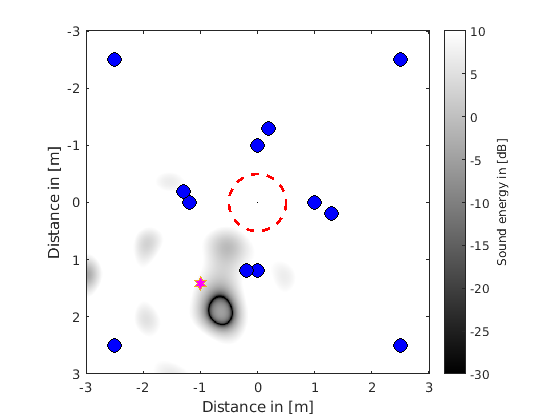

Nulm = zeros(N+1,2*N+1,nlspkr);

for i = 1:size(lspkr,2)
    [rho_i,the_i,phi_i] = my_cart2sph(lspkr(:,i));
    waveFun = @(R,the,phi) ISMspherical(rho_i,the_i,phi_i,R,the,phi,room,mag,phase,omega,c,alpha,order);
    [Nulm(:,:,i),~] = harmonicCoefficients(R,rho_k,N,waveFun,n,wave,0);
end

Nu = zeros(size(B,1),size(lspkr,2));
for i = 1:nlspkr
    id = 1;
    for idl=1:(N+1)
        l = idl-1;
        for idm=1:(2*l+1)
            Nu(id,i) = Nulm(idl,idm,i);
            id = id+1;
        end
    end
end

### Louspeaker Driving Signal

d = -pinv(Nu)*B;

###  Secondary Sound Field

s_xk = zeros(sz(1),sz(2),nlspkr);
h = waitbar(0,"init");
for i=1:nlspkr
    
    [rho_i,the_i,phi_i] = my_cart2sph(lspkr(:,i));
    for idy = 1:sz(1)
        for idx = 1:sz(2)
            [rho,the,phi] = my_cart2sph([rx(idx);ry(idy);0]);
            G = ISMspherical(rho_i,the_i,phi_i,rho,the,phi,room,mag,phase,omega,c,alpha,order);
            s_xk(idy,idx,i) = G*d(i);
        end
    end
    waitbar(i/size(lspkr,2),h,"loading...");
     
end
close(h);

### Residual Noise Field

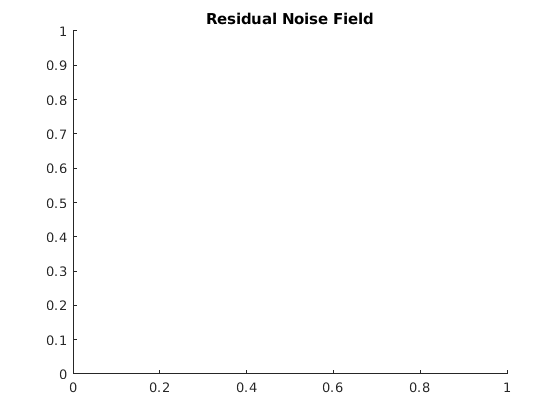

e = wave;
for i=1:nlspkr
    e = e+s_xk(:,:,i);
end
figure;

title("Residual Noise Field")
caxis([-30 ,10]);   

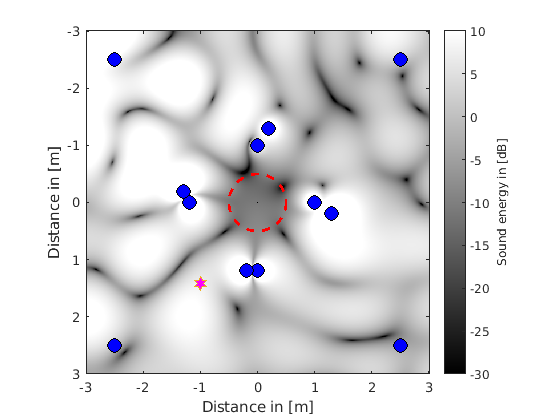

setupPlot(e,mic,lspkr,S,R,n,spacing,2,1);